# Performance of Different Implementations of MMM with Outer P Loop 

This Live Script helps you view the performance of implementations of MMM that, in one form or another, the three loops so that the P loop is the outer loop.  Some implementations cast computation in terms of vector-vector operations.  Some cast them in terms of matrix-vector operations.

To gather the performance data, implement and time, in the usual way,

    Gemm_PIJ.c                     (Execute 'make test_PIJ'.)

    Gemm_PI_Axpy.c            (Execture ... )

    Gemm_PI_daxpy.c

    Gemm_PI_bli_daxpyv.c

    Gemm_P_Ger_I_Axpy.c

    Gemm_PJI.c                     (Execute 'make test_PJI'.)

    Gemm_PJ_Axpy.c            (Execture ... )

    Gemm_ PJ_daxpy.c

    Gemm_PJ_bli_daxpyv.c

    Gemm_P_Ger_J_Apy.c

    Gemm_P_dger.c

    Gemm_P_bli_dger.c    

To make it easy to add to the graph incrementally as you implement these different routines, as you add new implementations, change the 'NO' to a 'YES'.  If the refence is to be plotted, then the top of the graph is also adjusted to the theoretical peak performance.  

clear all

plot_ref = 'NO';           % indicate if reference is to be plotted

plot_PIJ = 'YES';          % indicate ...
plot_PI_Axpy = 'YES';
plot_PI_daxpy = 'YES';
plot_PI_bli_daxpyv = 'YES';
plot_P_Ger_I_Axpy = 'YES';
plot_PJI = 'YES';
plot_PJ_Axpy = 'YES';
plot_PJ_daxpy = 'YES';
plot_PJ_bli_daxpyv = 'YES';
plot_P_Ger_J_Axpy = 'YES';
plot_P_dger = 'YES';
plot_P_bli_dger = 'YES';

When completed, these creates output files 'output_<version>.m' with timing data.  This Life Script then creates graphs from that timing data.

## Load data, check accuracy, and plot timing data

turbo_clock_rate = 2.6;
flops_per_cycle = 16;
peak_gflops = 2.6 * 16;

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

if strcmp( plot_PIJ, 'YES' )
    % Load data for PIJ
    output_PIJ
    
    if strcmp( plot_ref, 'YES' )
        % Plot time data for reference 
        plot( data(:,1), data(:,3), ...
              'MarkerSize', 8, 'LineWidth', 2, ...
              'DisplayName', 'reference', 'Color', [0 0 0] );
    end
      
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PIJ                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-', 'Color', [0 0 0] );
end

It appears all is fine



if strcmp( plot_PI_Axpy, 'YES' )
    % Load data for PI_Axpy
    output_PI_Axpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PI_Axpy              
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine



if strcmp( plot_PI_daxpy, 'YES' )
    % Load data for PI_daxpy
    output_PI_daxpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PI_daxpy             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 1 0] );
end

It appears all is fine



if strcmp( plot_PI_bli_daxpyv, 'YES' )
    % Load data for PI_bli_daxpyv
    output_PI_bli_daxpyv
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PI_bli_daxpyv             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 1 1] );
end

It appears all is fine



if strcmp( plot_P_Ger_I_Axpy, 'YES' )
    % Load data for P_Ger_I_Axpy
    output_P_Ger_I_Axpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for P_Ger_I_Axpy           
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [1 0 0] );
end

It appears all is fine



if strcmp( plot_PJI, 'YES' )
    % Load data for PJI
    output_PJI
    
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PJI                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-', 'Color', [0 0 0] );
end

It appears all is fine



if strcmp( plot_PJ_Axpy, 'YES' )
    % Load data for PJ_Axpy
    output_PJ_Axpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PJ_Axpy             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine



if strcmp( plot_PJ_daxpy , 'YES' )
    % Load data for PJ_daxpy
    output_PJ_daxpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PJ_daxpy             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0 1 0] );
end

It appears all is fine



if strcmp( plot_PJ_bli_daxpyv, 'YES' )
    % Load data for PJ_bli_daxpyv
    output_PJ_bli_daxpyv
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PJ_bli_daxpyv             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0 1 1] );
end

It appears all is fine



if strcmp( plot_P_Ger_J_Axpy, 'YES' )
    % Load data for P_Ger_J_Axpy
    output_P_Ger_J_Axpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for P_Ger_J_Axpy            
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [1 0 0] );
end

It appears all is fine



if strcmp( plot_P_dger, 'YES' )
    % Load data for P_dger
    output_P_dger
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for P_dger              
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'x', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine



if strcmp( plot_P_bli_dger, 'YES' )
    % Load data for P_bli_dger
    output_P_bli_dger
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for P_bli_dger              
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'x', ...
          'LineStyle', '-.', 'Color', [0 1 0] );
end

It appears all is fine


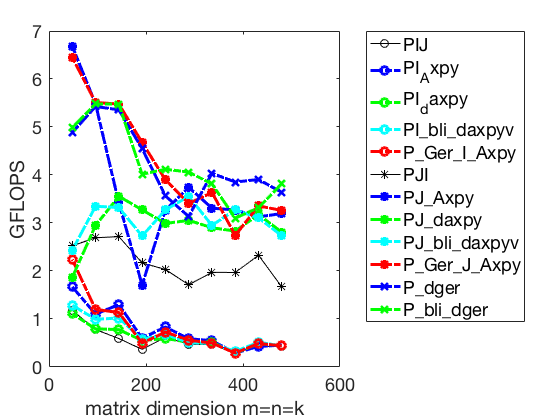




% Create ylabel
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeastoutside','FontSize',18);

if strcmp( plot_ref, 'YES' )
    % Adjust the x-axis and y-axis range to start at 0 and top of graph is peak
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 peak_gflops ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
else
    % Adjust the x-axis and y-axis range to start at 0
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
end